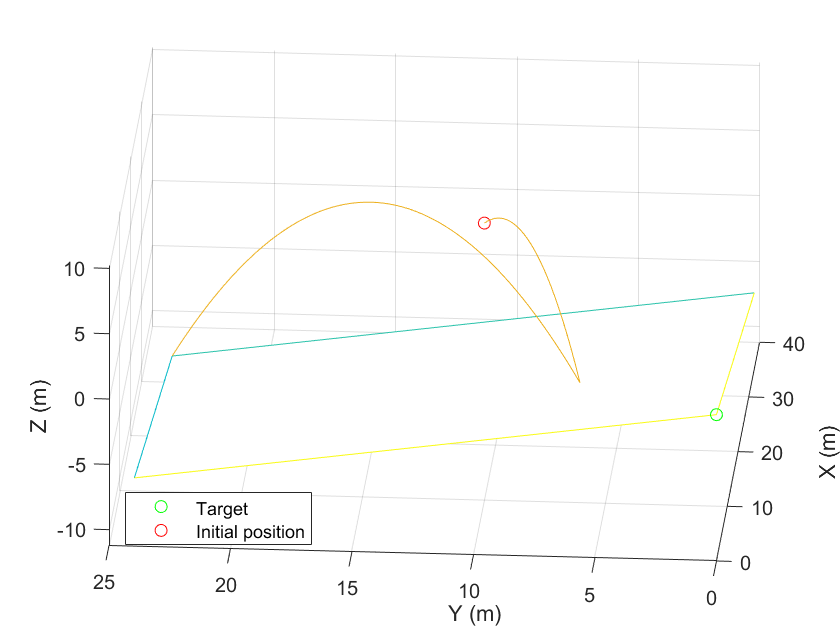

nBounces = 2;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 10];
v_0 = [2; -2; 2];
normal = [0.15; 0.25; 1]; % this value may be overwritten later
origin = [0; 0; 0];

[T, States, ~, endTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @(~, ~)(normal), [0, 0], true);
figure()
plot_bounce(States, p_0, normal', T, endTimes);
view([274.1 38.1])


States(T == endTimes(1), :) % the location of the first bounce


ans =

  0×6 empty double matrix



States(T == endTimes(2), :) % this should be very close to the origin if all the math is right


ans =

  0×6 empty double matrix



## Stationary target:

To simulate the bouncing ball control for a stationary target, simply pass an <X, Y> position vector to mark out the desired target position. For stationary targets, an `nBounces` has to be manually determined.

timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [100; 100; 20];
v_0 = [2; -2; 2];

stationary_target = [0, 0];
nBounces = 20;
[T, States, Normals, Targets, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, stationary_target, true);

## Moving targets:

With moving targets, the syntax is a bit different:

- Instead of just a vector for a target position, `Targets` is now a row matrix of target X and Y positions. Note that these are desired bounce positions, matching the indices of the bounces. Since the first bounce is never accurate the first "target" position can be diregarded.

- Since we have a bunch of target bounces, we want to determine the number of bounces based on the amount of target positions. Conveniently, they should be equal to each other

%nBounces = 10;
timeout = 10; % seconds
coeff_restitution = 0.95; % unitless
g = 9.80; % m/s^2

p_0 = [10; 10; 10];
v_0 = [2; -2; 2];
origin = [0; 0; 0];

Targets = [0, 0
            0, 0;
            1, 1;
            2, 2;
            2, 2;
            2, -2;
            -3, 3;
            0, 0;
            0, 0;];

nBounces = size(Targets, 1);

[T, States, Normals, Targets, bounceTimes] = bounceSim(nBounces, timeout, [p_0, v_0], g, coeff_restitution, origin, @calculate_normal, Targets, true);

## Animation:

NOTE: The simulations run **much** faster when not in a livescript. If possible, call the below function from your command window instead.

The bounce animation function takes existing simulation data and simulates it. Note that you must first simulate the bouncing with `bounceSim` first. `bounce_animation` merely animates the states generated by `bounceSim`.

% Simulate, without saving gif:
bounce_animation(T, States, Normals, Targets, false)

% Simulate, and save gif:
bounce_animation(T, States, Normals, Targets, true)